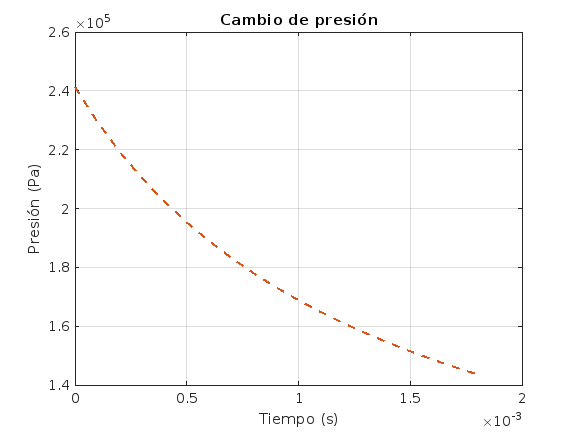

clear; clc; close all;

P0 = 241317;
Patm = 101300;
Vo = 0.0015;
rho_aire = 1.2;
rho_agua = 1000;
A = 0.04398;
t_inicial = 0;
t_final = 15.0;
dt = 0.0001;
mc = 0.899;
mc_vacio = 0.399;
Vt = 0.002;

D = 5;
ang = deg2rad(90); % Cambio a radianes
v0 = 10; % Magnitud 

t = t_inicial:dt:t_final;
nsteps = length(t);
P = zeros(1, nsteps);
P(1) = P0;

masa = zeros(1, nsteps);
masa(1) = mc;

vy = zeros(1, nsteps);
y = zeros(1, nsteps);
y(1) = 0.50;
vy(1) = v0 * sin(ang);


for i = 2:nsteps
    P(i) = calcularPresion(P(i - 1), P0, Vo, A, rho_agua, Patm, dt);
    masa(i) = masavariable(mc, rho_agua, Vt, P0, Vo, P(i));
    v = sqrt(vy(i-1)^2);
    uy = vy(i-1) / v;

    vy(i) = vy(i-1) + 2*((P(i)-Patm)/masa(i)) - (v * vy(i) * D / masa(i)) - (9.81)*t(i);

    y(i) = y(i-1) + vy(i) * dt;
    if (P(i) <= Patm) || (masa(i) <= mc_vacio && P(i) >= Patm)
        nsteps = i;
        break;
    end
end



t = t(1:nsteps);
P = P(1:nsteps);
masa = masa(1:nsteps);
y=y(1:nsteps);
vy=vy(1:nsteps);


figure;
plot(t, P, '--', 'LineWidth', 1.5, 'Color', '#D95319');
xlabel('Tiempo (s)');
ylabel('Presión (Pa)');
title('Cambio de presión');
set(gcf, 'Visible', 'on');
grid on;

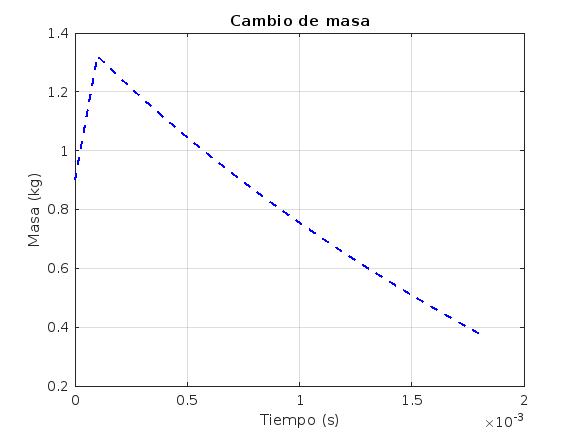


figure;
plot(t, masa, '--', 'LineWidth', 1.5, 'Color', 'blue');
xlabel('Tiempo (s)');
ylabel('Masa (kg)');
title('Cambio de masa');
set(gcf, 'Visible', 'on');
grid on;

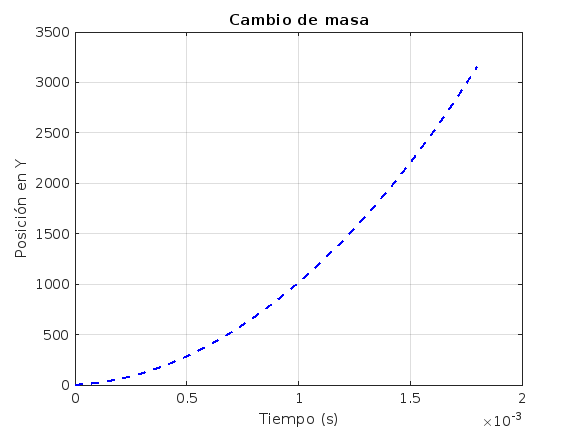



figure;
plot(t, y, '--', 'LineWidth', 1.5, 'Color', 'blue');
xlabel('Tiempo (s)');
ylabel('Posición en Y');
title('Gráfica de posición');
set(gcf, 'Visible', 'on');
grid on;

function Pn = calcularPresion(Pn_1, P0, Vo, A, rho_agua, Patm, dt)
    Pn = Pn_1 - (((Pn_1^2)*(A)/((P0)*Vo))*sqrt(2*(Pn_1-Patm)/rho_agua))*dt;
end

function mn = masavariable(mc, rho_agua, Vt, P0, Vo, P)
    mn = mc + rho_agua * ((Vt - (P0 * Vo) ./ P));
end

